**WILL TIRONE MAT 343**

**LAB 5 - LEAST SQUARES**

**QUESTION 1 **

**a) **

type Example1Modified.m

format short e 
dat = load("gco2.dat");
x = dat(:,1);
y = dat(:,2);
X = [ones(size(x)),x];             % build the matrix X for linear model
z = X'*y;                         % right hand side of the Normal Equations
S = X'*X;                         % Left hand side of the Normal Equations
U = chol(S);                      % Cholesky decomposition
w = U'\z;  %solve the normal equations using the Cholesky decomposition
c = U\w
plot(x,y,'o')   % plot the data points
q = x;    % define a vector for plotting the linear function
fit = c(1)+c(2)*q;  %define the linear fit 
hold on   
plot(q,fit,'Linewidth',2); 
axis tight 
hold off


c =   -3.1538e+03
   1.7627e+00


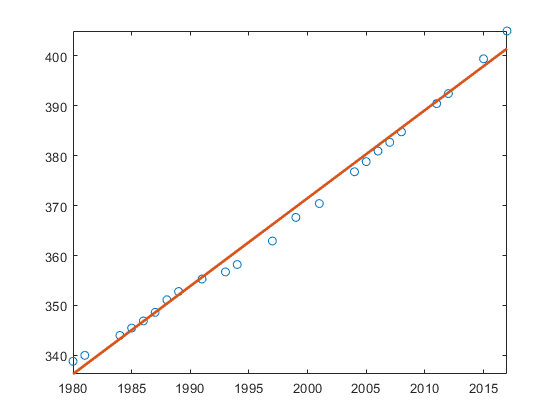

Example1Modified

**b) **

type Example1Modified_Quadratic.m

format short e 
dat = load("gco2.dat");

x = dat(:,1);
y = dat(:,2);

X_lin = [ones(size(x)),x];
X_quad = [ones(size(x)),x,x(:,1).^2];

z_lin = X_lin'*y;                         % right hand side of the Normal Equations
S_lin = X_lin'*X_lin;                         % Left hand side of the Normal Equations
U_lin = chol(S_lin);                      % Cholesky decomposition
w_lin = U_lin'\z_lin;  %solve the normal equations using the Cholesky decomposition
c_lin = U_lin\w_lin

z = X_quad'*y;                         % right hand side of the Normal Equations
S = X_quad'*X_quad;                         % Left hand side of the Normal Equations
U = chol(S);                      % Cholesky decomposition
w = U'\z;  %solve the normal equations using the Cholesky decomposition
c = U\w

plot(x,y,'o')   % plot the data points
q = x;    % define a vector for plotting the linear function

lin_fit = c_lin(1)+c_lin(2)*q; 
quad_fit = c(1)+c(2)*q+c(3)*q.^2;  %define the linear fit 

hold on   

plot(q,qua

c_lin =   -3.1538e+03
   1.7627e+00


c =    5.6192e+04
  -5.7619e+01
   1.4854e-02


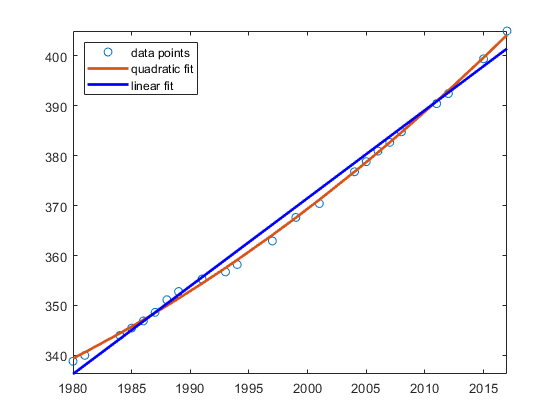

Example1Modified_Quadratic

**QUESTION 2 **

**a) **

type Question_2_a.m

format short e 

t = [0; 5; 10 ;15; 20; 25];
y = [15; 15.7 ;18.7 ;20 ;21.9; 24.8];
Y = log(y);

X = [ones(size(t)),t]

z = X'*Y;                         % right hand side of the Normal Equations
S = X'*X;                         % Left hand side of the Normal Equations
U = chol(S);                      % Cholesky decomposition
w = U'\z;  %solve the normal equations using the Cholesky decomposition
c = U\w

plot(t,Y,'o')   % plot the data points
q = t;    % define a vector for plotting the linear function
fit = c(1)+c(2)*q;  %define the linear fit 

hold on   
plot(q,fit,'Linewidth',2); 
axis tight 
hold off


X =      1     0
     1     5
     1    10
     1    15
     1    20
     1    25


c =    2.6915e+00
   2.0455e-02


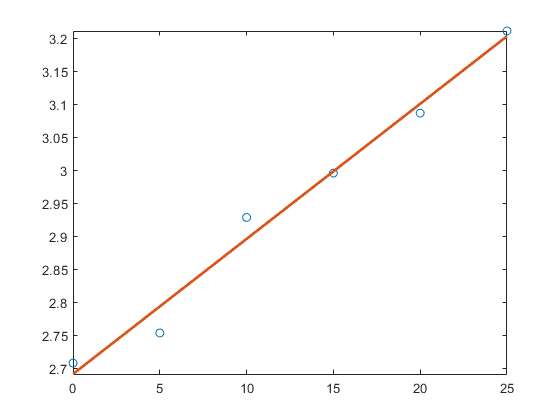

Question_2_a

**b) **

type Question_2_b.m

t = [0; 5; 10 ;15; 20; 25];
y = [15; 15.7 ;18.7 ;20 ;21.9; 24.8];
Y = log(y); 

X = [ones(size(t)),t]; 

z = X'*Y;                         % right hand side of the Normal Equations
S = X'*X;                         % Left hand side of the Normal Equations
U = chol(S);                      % Cholesky decomposition
w = U'\z;  %solve the normal equations using the Cholesky decomposition
c = U\w

plot(t,y,'o')   % plot the data points
q = [0:.1:35];    % define a vector for plotting the linear function
fit = exp(c(1))*exp(c(2)*q);  %define the linear fit 

hold on   
plot(q,fit,'Linewidth',2); 
hold off


c =    2.6915e+00
   2.0455e-02


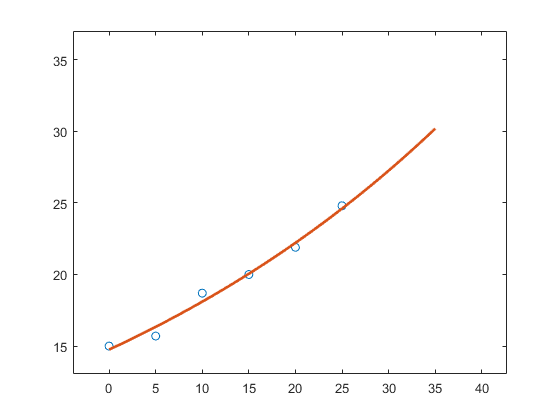

Question_2_b

**c) Use your model to predict when the balance will reach $30,000 dollars.**

I've just extended the q range and manually looked at where balance, the y axis, reaches 30 ($ in thousands). As mentioned in the lab notes though this is probably not very accurate. 

**QUESTION 3**

**a)**

type Question3_a.m

format short e 
dat = load("gco2.dat");

%x = dat(:,1);
%y = dat(:,2);

m = [1:1:12]'; 
Y = [4.9; 5.5; 6.5; 7.1; 7; 6.8; 6.2; 6; 6.4; 6; 5.3; 4.8;];


%X = [ones(size(x)),x];             % build the matrix X for linear model
X = [ones(size(m))]; 

a = []; 
for i = 1:5 
    a(:,i) = m(:,1).^i;
end

X_fifth = [X, a]; 

z = X_fifth'*Y;                         % right hand side of the Normal Equations
S = X_fifth'*X_fifth;                         % Left hand side of the Normal Equations
U = chol(S);                      % Cholesky decomposition
w = U'\z;  %solve the normal equations using the Cholesky decomposition
c = U\w

plot(m,Y,'o')   % plot the data points
q = [1:0.1:12];    % define a vector for plotting the linear function
fit = c(1)+c(2)*q+c(3)*q.^2+c(4)*q.^3+c(5)*q.^4+c(6)*q.^5;  %define the linear fit 

hold on   
plot(q,fit,'Linewidth',2); 
axis tight 
hold off


c =    4.3364e+00
   5.1864e-02
   5.8469e-01
  -1.6542e-01
   1.6239e-02
  -5.4393e-04


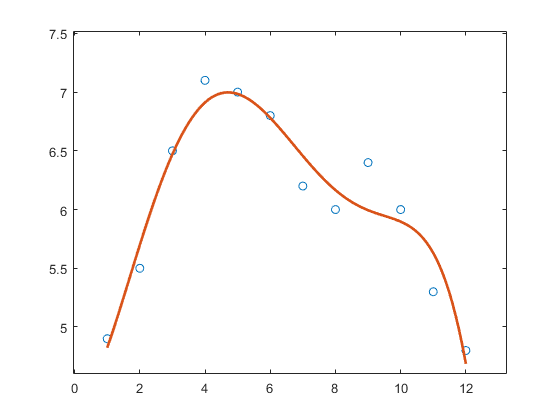

Question3_a

**b) **

How do the values of c compare to the ones you found in part (a)?

- the answers are identical 

How does the plot compare to the one you found in part (a)?

- it looks like the plots are also identical

type Question3_b

m = [1:1:12]'; 
Y = [4.9; 5.5; 6.5; 7.1; 7; 6.8; 6.2; 6; 6.4; 6; 5.3; 4.8;];

X = [ones(size(m))]; 

a = []; 
for i = 1:5 
    a(:,i) = m(:,1).^i;
end

X_fifth = [X, a]; 

c = X_fifth\Y
c = c ([6: -1:1]) ;
q = 1:0.1:12;
z = polyval (c,q);
figure
plot (q,z,m,Y,'o');
axis tight


c =    4.3364e+00
   5.1864e-02
   5.8469e-01
  -1.6542e-01
   1.6239e-02
  -5.4393e-04


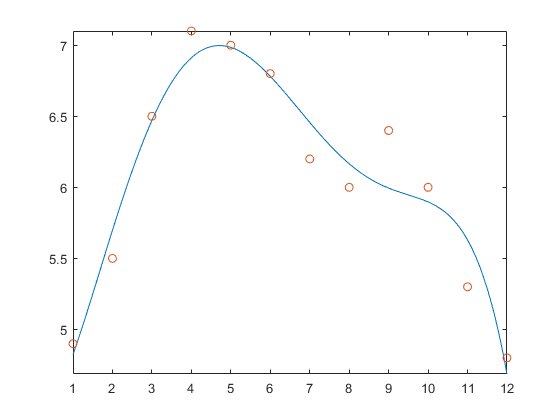

Question3_b